## Establish Serial Connection

% Open the port to which the Arduino is connected and create a serial object.

% @ port                - COM port address of the Arduino. This will change depending on which USB port
%                   the arduino is connected to, and the exact structure of the address will vary between
%                   operating systems

% @ baudrate            - BaudRate used between MATLAB and Arduino, which is limited to a max of
%                   230400 by MATLAB.

% @ numID               - Number of detected motors.

% @ ID                  - Vector containing ID of each detected motor.

% @ establishSerial()   - A helper function that creates and returns a serial object while also performing
%                   a handshake with the Arduino to confim connection.


% Specify COM Port
% port = '/dev/cu.usbmodem14131';                  % MacOS Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS
port = 'COM5';                                % Windows Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS

% Setup Serial Connection
baudrate = 230400;
fclose(s);
s = establishSerial(port, baudrate);
% s = serialport(port, baudrate);

% Read Connected Motor IDs
[numID, ID] = getMotorIDs(s)

numID = 5

ID =      1     2     3     4     5


% setControlMode(s, "velocity");

% Set Change Motor ID flag - CHANGE TO ADJUST MOTOR ID
changeMotorID = false;

angleError = [0,20,7,10]*pi/180;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% NOTE: Remember to fclose(s) before disconnecting your Arduino!!! %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% call some neccessary function to work with, i.e forward Kinematic,
% jacobian, etc in form of symbolic, so that we can just subs the number in
% to save the computational cost and time.

% forward Kinematics:
% r: end-effector pose in frame {0}
% T_eto0: Transformation mtx from e to 0
syms d1 d2 d3 d4 Q1 Q2 Q3 Q4 real;
[symsVar.r_E, symsVar.T_Eto0] = ForwardKinematic_EndEffector_to_0();


% jacobian matrix
[symsVar.J_inv,symsVar.J] = Jacobian_Matrix_ASM4();

% Set motor EPROM to position control mode
setControlMode(s, "position");

sendJointPos(s,[0],numID);

sendJointPos(s,[0,gripper.openQ], 2);

setControlMode(s, "velocity");

Index exceeds the number of array elements (4).

Error in sendJointVel (line 35)
        fprintf(s, '%s', num2str(jointVel(i)) + "e");

sendJointVel(s, [0 0 0 0], numID);

sendJointPos(s,[0,15*pi/180, -40*pi/180,-80*pi/180], numID);

Index exceeds the number of array elements (4).

Error in sendJointPos (line 34)
        fprintf(s, '%s', num2str(jointPos(i)) + "e");

% sendJointPos(s,[0/2 0/2], numID);


readMotorFB(s,numID)*180/pi

ans =     4.3373  -45.3253  -41.4217  -45.5422  -57.1289


readMotorFB(s,numID)

ans =     0.0757   -0.7911   -0.7229   -0.7949   -0.9971


double(substituteVariable(symsVar.r_E,fixAngleFromMotorFB(ans(1:4))))

% test 4 corners for calibration
corner1 = [260;140;110]; motorQ1 = fixAngleToMotorFB(InverseKinematicsGeneric(corner1));
corner2 = [260;-140;110]; motorQ2 = fixAngleToMotorFB(InverseKinematicsGeneric(corner2));
corner3 = [540;140;180]; motorQ3 = fixAngleToMotorFB(InverseKinematicsGeneric(corner3));
corner4 = [540;-140;180]; motorQ4 = fixAngleToMotorFB(InverseKinematicsGeneric(corner4));
sendJointPos(s,[motorQ2+angleError,gripper.openQ], numID);

% Set Motor internal PID controller. Gains must be integers.
tmpID = 1;      % motor id
Kp = 6; Ki = 1; Kd = 0;
setPID(s, tmpID, Kp, Ki, Kd)
setPID(s, 2, 7, 2, 0)       % motor 2
setPID(s, 3, 5, 2, 0)       % motor 3
setPID(s, 4, 5, 1, 0)       % motor 4
setPID(s, 5, 3, 0, 0)

% STEP 1: IMPORT ALL THE TRAJECTORY INTO WORKSPACE
% ---------------------------------------------------------------
% edit the move ID will gen the required square on chessboard

% listOfMove will gen the code of the square
% Square = listOfMove(moveID);

% motion_planning will return the required trajectory for the task
% expect running time: 10s
for moveID = 2
    trajectoryStruct.traj(moveID) = motion_planning_ASM4(listOfMove(moveID));
    fprintf("Done -- moveID --- " + string(moveID) + "\n");
end

Done -- moveID --- 2


% CALCULATE ANGLE FOR HOME POSITION
Q           = InverseKinematicsGeneric([300;0;310]);
homeMotorQ  = fixAngleToMotorFB(Q);

% define the angle of the grippper
gripper.closeQ  = 0.18;
gripper.openQ   = -0.65;
gripper.Q       = gripper.openQ; % as default

GetBackHome(s, numID, homeMotorQ,gripper.openQ, angleError);
angle = [homeMotorQ+angleError,gripper.openQ];
% sendJointPos(s,angle, numID);
readMotorFB(s,numID)

ans =     0.0076   -0.7267   -1.2415   -1.1393   -1.9226


(readMotorFB(s,numID))*180/pi

ans =     0.4337  -41.6385  -70.9156  -66.1446 -109.8633


% This is where you will write the majority of your code for part 2 of the project.
% get the data to control by edit the moveID
moveID      = 2;
trajectory = trajectoryStruct.traj(moveID);

feedback.motor.Q    = [];
feedback.ref.Q      = [];
feedback.pose       = [];
for i = 1:1
    N   = length(trajectory.segment(i).poseRef(1,:));
    ref = trajectory.segment(i);
%     plot3(ref.poseRef(1,:),ref.poseRef(2,:),ref.poseRef(3,:),'-o','Color','r');
    for j = 1:N
%         Visualization_pose(ref.poseRef(:,j));
        r       = round(ref.poseRef(:,j));
        Q       = InverseKinematicsGeneric(r);
        motorQ  = fixAngleToMotorFB(Q);
        fprintf("At i, j: %d, %d",i,j);
        fprintf("Ref angle: \n");
        Q
        sendJointPos(s,[motorQ+angleError,gripper.Q], numID);
        pause(0.01);
        fprintf("Motor angle: \n");
        fixAngleFromMotorFB(readMotorFB(s,numID))
        
        % ______ print result for debugging _____

        feedback.ref.Q(:,j)     = Q';
        feedback.motor.Q(:,j) = fixAngleFromMotorFB(readMotorFB(s,numID))'
        feedback.pose(:,j) = double(substituteVariable(symsVar.r_E,feedback.motor.Q(:,j)));
    end
    
    pause(3);
    if (i == 1)
            fb = readMotorFB(s,numID)
            pause(3);
            triggerTheGripper(s,fb(1:4),gripper.closeQ,numID);
            gripper.Q = gripper.closeQ;
    elseif (i == 2)
            fb = readMotorFB(s,numID)
            pause(3);
            triggerTheGripper(s,fb(1:4),gripper.openQ,numID);
            gripper.Q = gripper.openQ;
%             GetBackHome(s, numID, homeMotorQ,gripper.openQ, angleError);
    end
pause(3);
end

At i, j: 1, 1

Ref angle: 


Q =          0    1.5273   -1.6613   -1.4368


Motor angle: 


ans =    -0.0038    1.8282   -1.5727   -1.2983


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: []


At i, j: 1, 2

Ref angle: 


Q =    -0.1767    1.5362   -1.8657   -1.2413


Motor angle: 


ans =    -0.1628    1.8282   -1.8301   -1.1393


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×1 double]


At i, j: 1, 3

Ref angle: 


Q =    -0.3672    1.4710   -2.0047   -1.0371


Motor angle: 


ans =    -0.3671    1.8017   -1.9588   -0.9198


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×2 double]


At i, j: 1, 4

Ref angle: 


Q =    -0.3672    1.4710   -2.0047   -1.0371


Motor angle: 


ans =    -0.3671    1.8017   -1.9588   -0.9198


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×3 double]


At i, j: 1, 5

Ref angle: 


Q =    -0.3672    1.3299   -2.0940   -0.8067


Motor angle: 


ans =    -0.3709    1.6049   -2.0042   -0.6586


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×4 double]


At i, j: 1, 6

Ref angle: 


Q =    -0.3672    1.1435   -2.1365   -0.5778


Motor angle: 


ans =    -0.3747    1.4118   -2.0496   -0.4201


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×5 double]


fb =     0.3747   -0.1590   -1.2642   -0.4239   -0.5113


At i, j: 2, 1

Ref angle: 


Q =    -0.3672    1.1435   -2.1365   -0.5778


Motor angle: 


ans =    -0.3634    1.4118   -2.0799   -0.4239


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 2

Ref angle: 


Q =    -0.3672    1.3299   -2.0940   -0.8067


Motor angle: 


ans =    -0.3634    1.5822   -2.0799   -0.6245


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 3

Ref angle: 


Q =    -0.3672    1.4710   -2.0047   -1.0371


Motor angle: 


ans =    -0.3634    1.7600   -2.0193   -0.8668


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 4

Ref angle: 


Q =    -0.3672    1.4710   -2.0047   -1.0371


Motor angle: 


ans =    -0.3671    1.7600   -2.0193   -0.8706


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 5

Ref angle: 


Q =    -0.2606    1.4019   -1.8471   -1.1256


Motor angle: 


ans =    -0.2839    1.7222   -1.8604   -0.9652


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 6

Ref angle: 


Q =    -0.1747    1.3166   -1.6675   -1.2199


Motor angle: 


ans =    -0.1930    1.6049   -1.6825   -1.0674


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 7

Ref angle: 


Q =    -0.1747    1.3166   -1.6675   -1.2199


Motor angle: 


ans =    -0.1930    1.6049   -1.6825   -1.0712


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×6 double]


At i, j: 2, 8

Ref angle: 


Q =    -0.1747    1.2254   -1.7765   -1.0197


Motor angle: 


ans =    -0.1930    1.5102   -1.6825   -0.8933


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×7 double]


At i, j: 2, 9

Ref angle: 


Q =    -0.1747    1.0965   -1.8434   -0.8239


Motor angle: 


ans =    -0.1893    1.3513   -1.7771   -0.6889


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×8 double]


fb =     0.1930   -0.2195   -0.9917   -0.6889    0.0460


At i, j: 3, 1

Ref angle: 


Q =    -0.1747    1.0965   -1.8434   -0.8239


Motor angle: 


ans =    -0.1930    1.2869   -1.7998   -0.6700


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


At i, j: 3, 2

Ref angle: 


Q =    -0.1747    1.2254   -1.7765   -1.0197


Motor angle: 


ans =    -0.1893    1.2869   -1.7922   -0.8365


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


At i, j: 3, 3

Ref angle: 


Q =    -0.1747    1.3166   -1.6675   -1.2199


Motor angle: 


ans =    -0.1893    1.3021   -1.6900   -1.0257


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


At i, j: 3, 4

Ref angle: 


Q =    -0.1747    1.3166   -1.6675   -1.2199


Motor angle: 


ans =    -0.1930    1.5292   -1.6825   -1.0674


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


At i, j: 3, 5

Ref angle: 


Q =    -0.0935    1.4315   -1.6795   -1.3228


Motor angle: 


ans =    -0.1022    1.5292   -1.6825   -1.1582


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


At i, j: 3, 6

Ref angle: 


Q =          0    1.5273   -1.6613   -1.4368


Motor angle: 


ans =    -0.0379    1.6124   -1.6825   -1.2604


feedback = struct with fields:
    motor: [1×1 struct]
      ref: [1×1 struct]
     pose: [3×9 double]


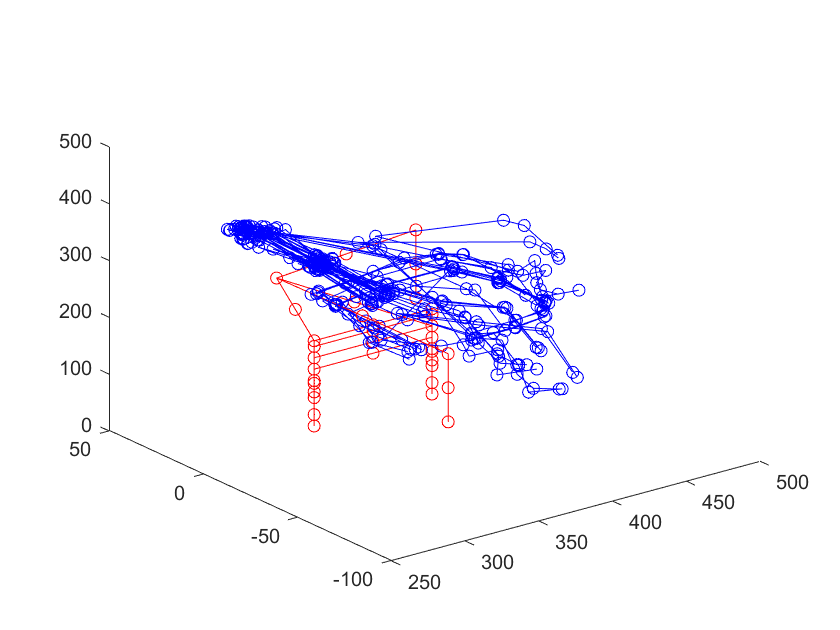



figure(1);
plot3(feedback.pose(1,:),feedback.pose(2,:),feedback.pose(3,:),'-o','color','b');hold on
plot3(ref.poseRef(1,:),ref.poseRef(2,:),ref.poseRef(3,:),'-o','Color','r');hold on

% VisualizationJointSpace(feedback.motor.Q(:,j));

fb = readMotorFB(s,numID)

fb =     0.0530   -0.4618   -1.4724   -0.8441   -0.5318


ans =     0.0530   -0.4618   -1.4724   -0.8441


triggerTheGripper(s,fb(1:4),gripper.closeQ,numID);

readMotorFB(s,numID)

ans =     0.0038    0.2422   -0.8289   -1.2945   -0.6085


fclose(s);

% ------ ADDITIONAL CODE -----------

function value = substituteVariable(symVariable,jointDisp)
syms d1 d2 d3 d4 Q1 Q2 Q3 Q4 real;

[D1,D2,D3,D4] = RobotSpec_Assembly();
q1 = jointDisp(1);
q2 = jointDisp(2);
q3 = jointDisp(3);
q4 = jointDisp(4);

value = subs(symVariable, [d1,d2,d3,d4,Q1,Q2,Q3,Q4], [D1,D2,D3,D4,q1,q2,q3,q4]);

end

function [x,y,z]= GetOrientation(R)
x = R(1:3,1);
y = R(1:3,2);
z = R(1:3,3);
end

function orError = getOrientationError(ref,fb)
orError = 1/2*[cross(fb.Xe,ref.Xe) + cross(fb.Ye,ref.Ye) + cross(fb.Ze,ref.Ze)];
end

function newAngle = fixAngleFromMotorFB(angle)

% q1Zero = -pi;
q2Zero = -pi/2; % Joint displacement for sensorID = 2 to return to zero position
q3Zero = pi/4; % _____________________________= 3 __________________________
q4Zero = 0;
offset = [q2Zero, q3Zero, q4Zero];

newAngle(1) = -angle(1);
newAngle(2:4) = angle(2:4) - offset;
end

function newAngle = fixAngleToMotorFB(angle)
% q1Zero = -pi;
q2Zero = -pi/2; % Joint displacement for sensorID = 2 to return to zero position
q3Zero = pi/4; % _____________________________= 3 __________________________
q4Zero = 0;
offset = [q2Zero, q3Zero, q4Zero];

newAngle(1) = -angle(1);
newAngle(2:4) = angle(2:4) + offset;
end

function newVel = fixVelMotor(vel)
newVel = vel;
newVel(1) = -vel(1);

end

function feedback = readMotorFB(s,numID)
% Read motor position feedback
[feedback, eFB] = readFB(s, numID);
% feedback                                       % Display motor feedback
end

function vel = convertFromSym(symVel)
for t = 1:length(symVel)
    v = symVel(t,1);
    vel(t,1) = v.val;
end

end

function Delay(N)
for ttt = 1:N

end
end

function GetBackHome(s, numID, motorQ,gripper, error)
% This is where you will write a sequence to send all of your joints to their home positions.
% For home position, [Q1 Q2 Q3 Q4] = [0, pi/2, -pi/2, -pi/2]
sendJointPos(s,[motorQ+error,gripper], numID);
readMotorFB(s,numID);
end

function triggerTheGripper(s,feedback,gripperQ,numID)
sendJointPos(s,[feedback,gripperQ], numID);
end
